### 2 Matlab Simulation

#### Exercise 1:

close all


s = tf('s');

#### Changing K for sys K/(tau*s+1)

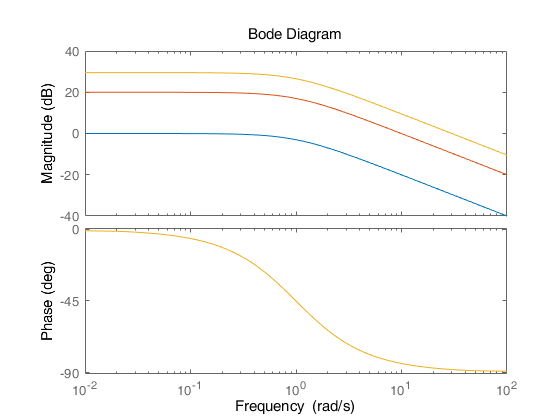

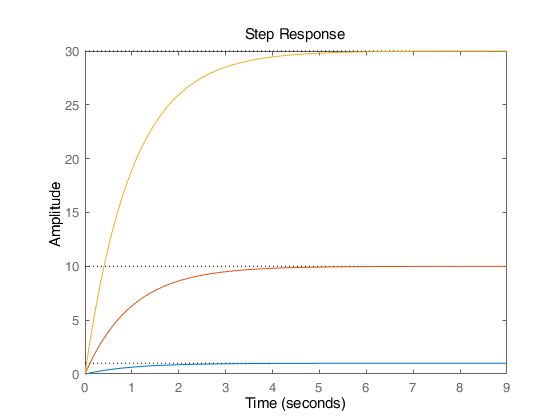

% Keep tau = 1
for K = [1 10 30]
    sys = K/(s+1);
    figure(1)
    step(sys);
    hold on 

    figure(2)
    bode(sys);
    hold on
end

**Changing tau for sys K/(tau*s+1)**

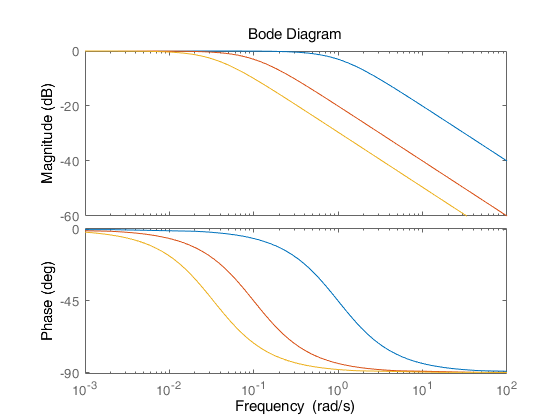

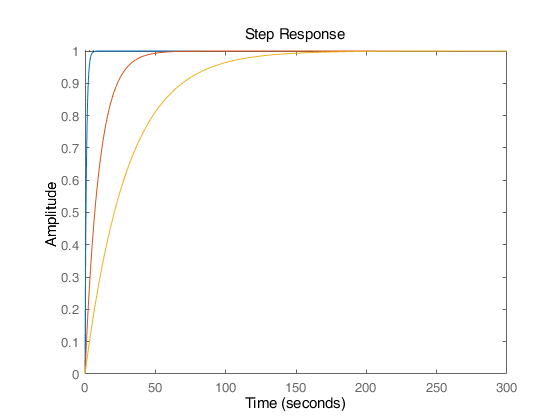

% Keep K = 1
for tau = [1 10 30]
    sys = 1/(tau*s+1);
    figure(3)
    step(sys);
    hold on 

    figure(4)
    bode(sys);
    hold on
end

**Changing omega for second order system**

% Keep omega = 1

omega = 1

omega = 1

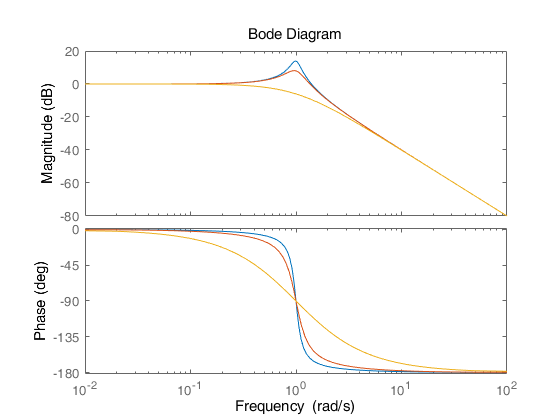

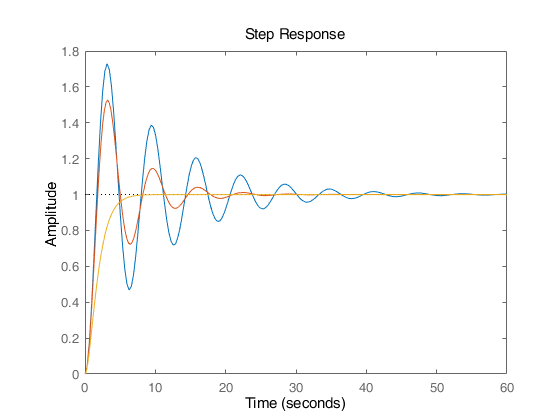

for phi = [0.1 0.2 1]
    sys = tf(omega^2, [1 2*phi*omega omega^2]);
    figure(5)
    step(sys)
    hold on
    
    figure(6)
    bode(sys);
    hold on
end

**Changing phi for second order system**

% Keep phi = 0.1
phi = 0.1

phi = 0.1000

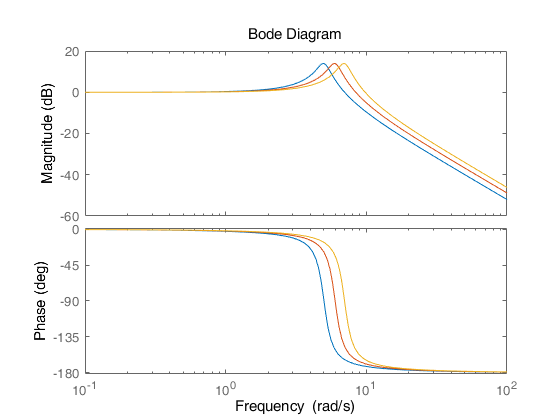

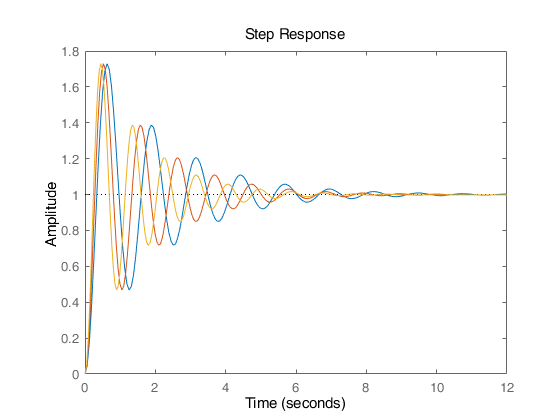

for omega = [5 6 7]
    sys = tf(omega^2, [1 2*phi*omega omega^2]);
    figure(7)
    step(sys)
    hold on
    
    figure(8)
    bode(sys);
    hold on
end

**Changing a for first order system**

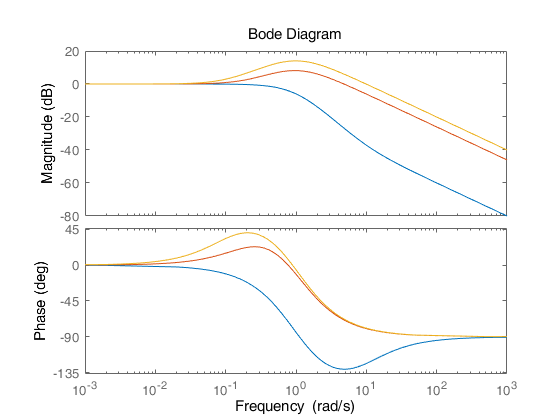

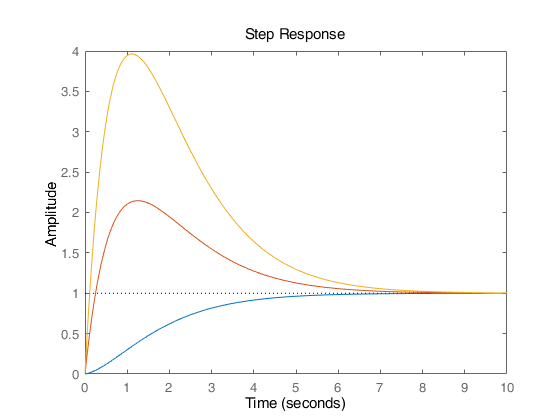


for a = [0.1 5 10]
    sys = (a*s+1)/(s+1)^2;
    figure(9)
    step(sys)
    hold on 
    
    figure(10)
    bode(sys)
    hold on
end

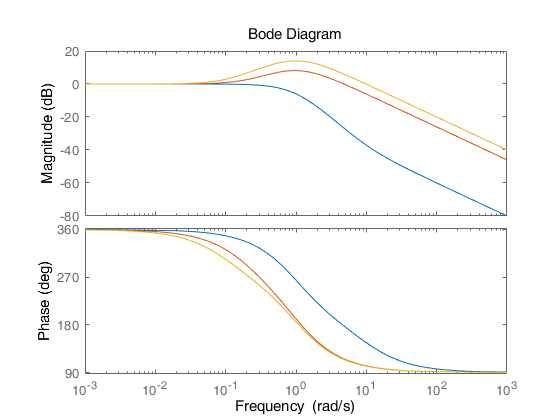

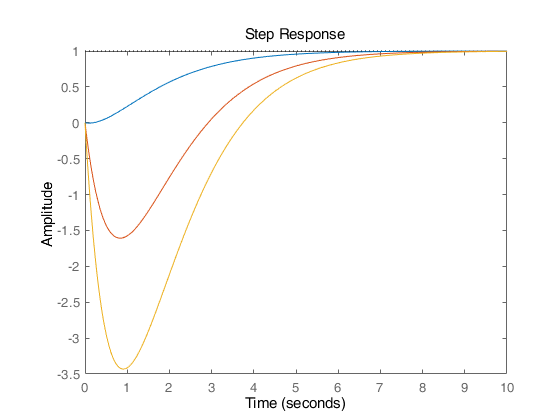


for a = [0.1 5 10]
    sys = (-a*s+1)/(s+1)^2;
    figure(11)
    step(sys)
    hold on 
    
    figure(12)
    bode(sys)
    hold on
end